# Graded Refractive Index Experiment

In real life, there is a high chance of a multiple graded refractive indexes in human tissue. The permittivity and permeability of the tissue will increase. The method in the paper used discreet differences in the refractive index. However if we take each layer to be the same thickness, and find the limit of the reflective signal. It could be possible to obtain an analytic function

## The Discreet function of the reflectivity in relation to the distance


$$\Gamma_i \left(\omega \right)=\frac{\rho_i +\Gamma_{i+1} e^{-2{\mathrm{jk}}_i l_i } }{1+\rho_i e^{-2{\mathrm{jk}}_i l_i } }$$


$\rho_i =\frac{1-\sqrt{\frac{\varepsilon_i }{\varepsilon_{i-1} }}}{1+\sqrt{\frac{\varepsilon_i }{\varepsilon_{i-1} }}}$e

where $\Gamma_i$ is the reflection reponse at the ith interface. Initialized by  $\Gamma_{m+1} =\rho_{m+1}$.

 $l_i$ is the thickness

${\text{k}}_i \left(\varepsilon ',\varepsilon \mathrm{''}\right)$is the propogation parameter (real and imaginary)

$n=\sqrt{\varepsilon_r }$  the refractive index

$k=\frac{2\pi n}{\lambda_0 }$ the propogation parameter

## Step 1

First we make assumptions. All layers $l\text{ }$are the same thickness. And then turn the reflection as a function of distance. Also ignore the frequency for now. Assume the frequency is constant. Because it is continuous. The discreet form of the permittivity of the equation is now become a series of step functions


$$\Gamma \left(y+\Delta y\right)=\frac{ \rho \left(y+\Delta y\right)+\Gamma \left(y\right)e^{-2\mathrm{jk}\left(y\right)\Delta y} }{1+\rho \left(y+\Delta y\right)e^{-2\mathrm{jk}\left(y\right)\Delta y} }$$


where the bottom interface of the multilayered structure is a dirac delta


$$\Gamma \left(0\right)=\rho \left(0\right)∗\delta \left(0\right)$$


and 


$$\rho \left(y+\Delta y\right)=\frac{1-\sqrt{\frac{\varepsilon \left(y+\Delta y\right)}{\varepsilon \left(y\right)}}}{1+\sqrt{\frac{\varepsilon \left(y+\Delta y\right)}{\varepsilon \left(y\right)}}}$$



$$k\left(y\right)=\frac{2\pi \sqrt{\varepsilon \left(y\right)}}{\lambda }$$


After taking the limit as $\Delta y$ goes to 0. The individual reflectivity $\rho$ becomes


$$\frac{d\left(\rho \left(y\right)\right)}{\mathrm{dy}}=\frac{1-\sqrt{\frac{d\left(\varepsilon \left(y\right)\right)}{\mathrm{dy}}}}{1+\sqrt{\frac{d\left(\varepsilon \left(y\right)\right)}{\mathrm{dy}}}}$$



$$\rho \left(y\right)=\int \frac{1-\sqrt{\frac{d\left(\varepsilon \left(y\right)\right)}{\mathrm{dy}}}}{1+\sqrt{\frac{d\left(\varepsilon \left(y\right)\right)}{\mathrm{dy}}}}\mathrm{dy}$$


Now we know p(y). We can find the rest of the reflection function


$$\Gamma \left(y+\Delta y\right)=\frac{\rho \left(y\right)+\Gamma \left(y\right)e^{-2\mathrm{ik}\left(y\right)\Delta y} }{1+\rho \left(y\right)e^{-2\mathrm{ik}\left(y\right)\Delta y} }$$


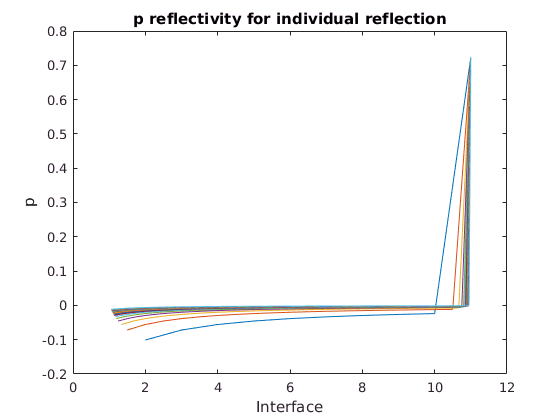

clc; clear;
Fc = 7.3e9;
lambda = 3e8/Fc;
k = 2 * pi ./ lambda;


i = 1;
for divs = 10:10:500
    layers = 1:divs;
    x{i} = layers./length(layers)*10;
    e{i} = layers./length(layers)*10+1;
    i = i + 1;
end

for i = 1:length(e)
    % First and last interface is 1
    ee = e{i};
    for j = 1 : length(e{i})-1
        pp(j+1) = (1-sqrt(ee(j+1)/ee(j)))/(1+sqrt(ee(j+1)/ee(j)));
        
    end
    pp(1) = (1-sqrt(ee(1)/1)/(1+sqrt(ee(1)/1)));
    pp(length(e{i})+1) = (1-sqrt(1/ee(length(e{i})))/(1+1/ee(length(e{i}))));
    p{i} = pp;
end

for i = 1:length(e)
    pp = p{i};
    plot(e{i}, pp(2:end));
    hold on;
end
hold off;
xlabel('Interface')
ylabel('p')
title('p reflectivity for individual reflection');

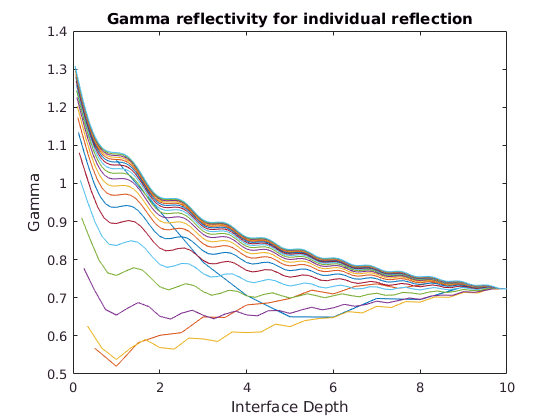


% Reflectivity
for i = 1:length(p)
    pp = p{i};
    ee = e{i};
    gg(length(pp)) = pp(end);
    l = 10/length(ee)*0.01;
    for j = length(pp)-1:-1:1
        n = sqrt(ee(j));
        exponent = exp(-2j*k*n*l);
        gg(j) = (pp(j) + gg(j+1)*exponent) ./ (1 + pp(j)*exponent);
    end
    g{i} = gg;
end

for i = 1:length(g)
   gg = g{i};
   plot(real(x{i}), abs(gg(2:end)));
   hold on;
end
hold off;

xlabel('Interface Depth')
ylabel('Gamma')
title('Gamma reflectivity for individual reflection');